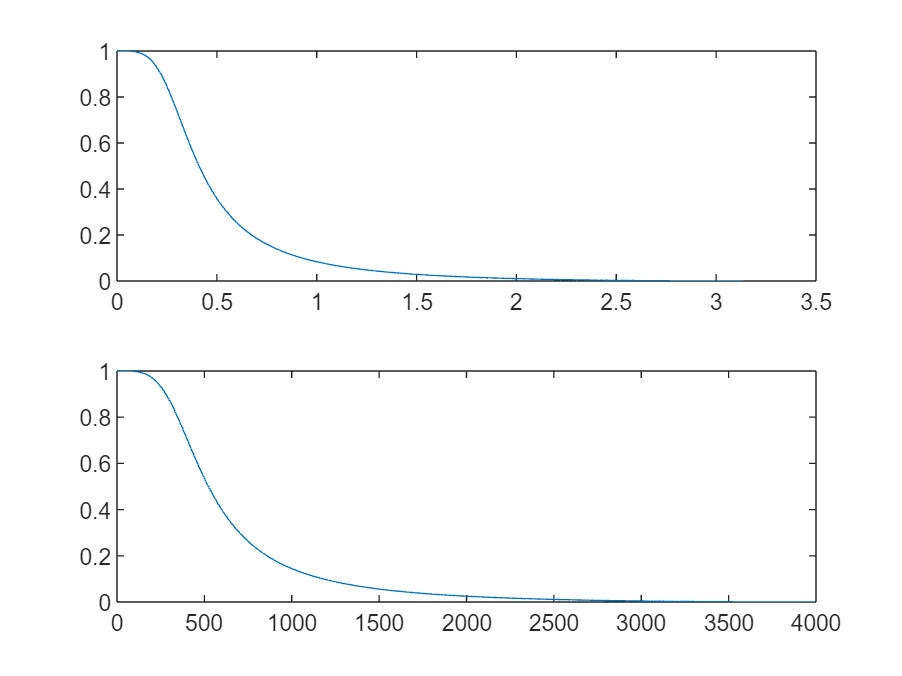

fs=8000;
[b,a]=butter(2,400/(fs/2));
[h,f]=freqz(b,a,512);
figure;
subplot(2,1,1),plot(f,abs(h));
[h,f]=freqz(b,a,512,fs);
subplot(2,1,2),plot(f,abs(h));

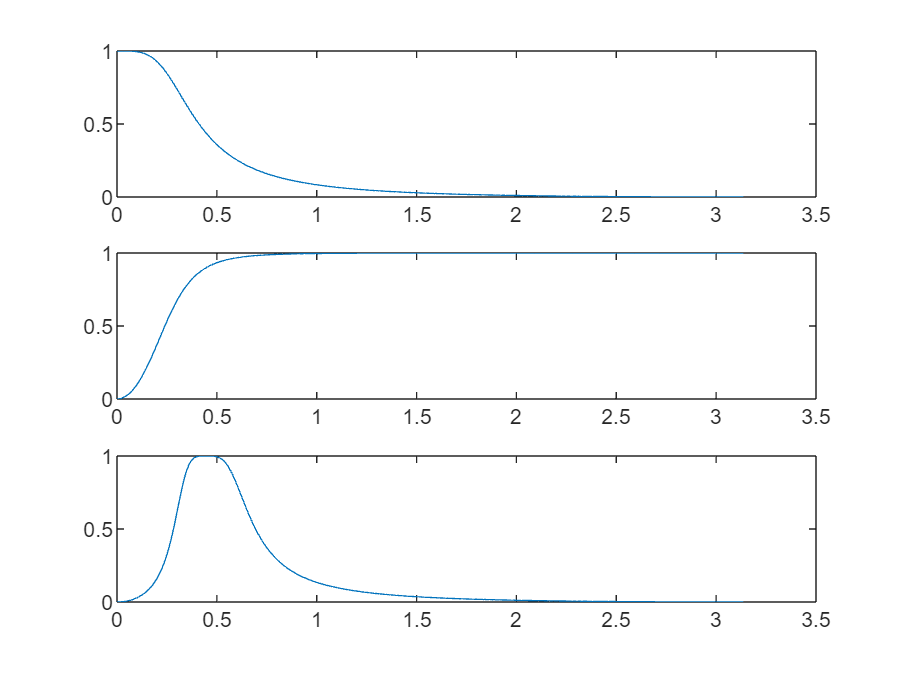

figure;
[b,a]=butter(2,400/(fs/2),'low');
[h,f]=freqz(b,a);
subplot(3,1,1),plot(f,abs(h));
[b,a]=butter(2,400/(fs/2),'high');
[h,f]=freqz(b,a);
subplot(3,1,2),plot(f,abs(h));
[b,a]=butter(2,[400 800]/(fs/2),'bandpass');
[h,f]=freqz(b,a);
subplot(3,1,3),plot(f,abs(h));

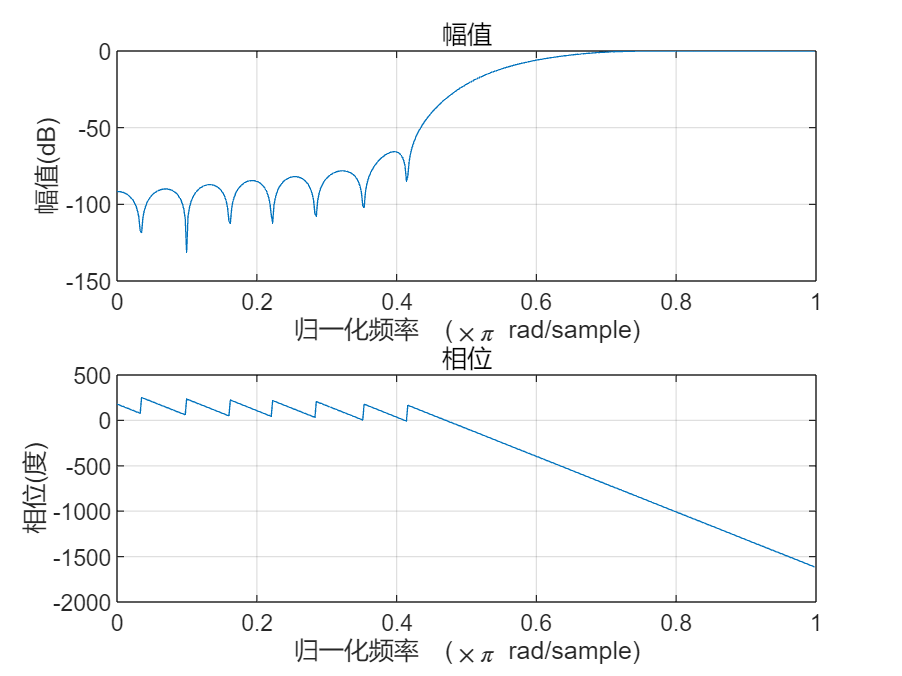

f=[0 0.5 0.7 1];
mhi=[0 0 1 1];
bhi=fir2(34,f,mhi);
freqz(bhi,1,512);

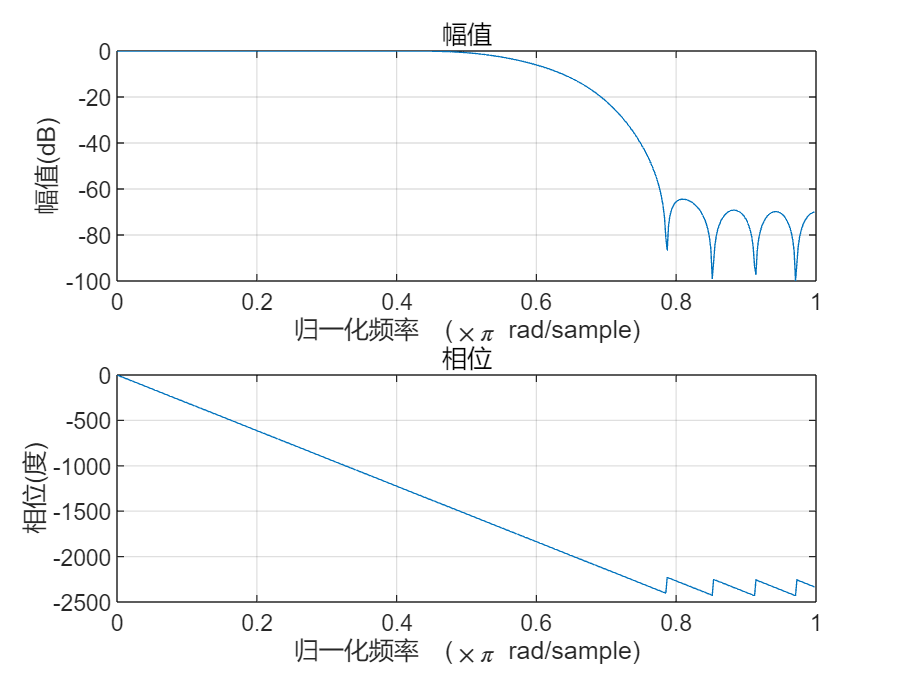

r=[0 0.5 0.7 1];
mlo=[1 1 0 0];
blo=fir2(34,r,mlo);
freqz(blo,1,512);

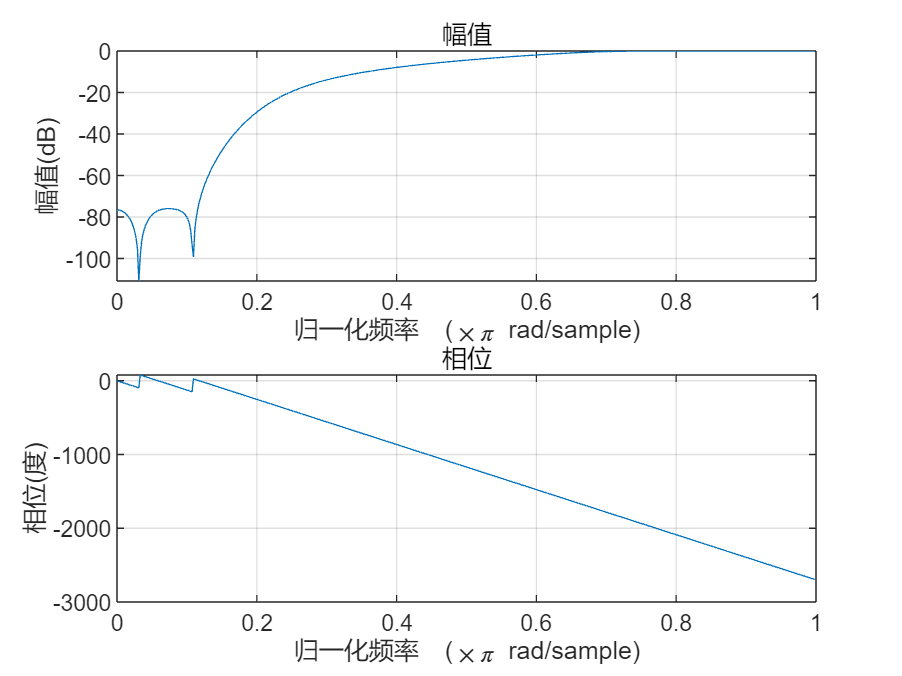

f=[0 0.2 0.7 1];
mhi=[0 0 1 1];
bhi=fir2(34,f,mhi);
freqz(bhi,1,512);

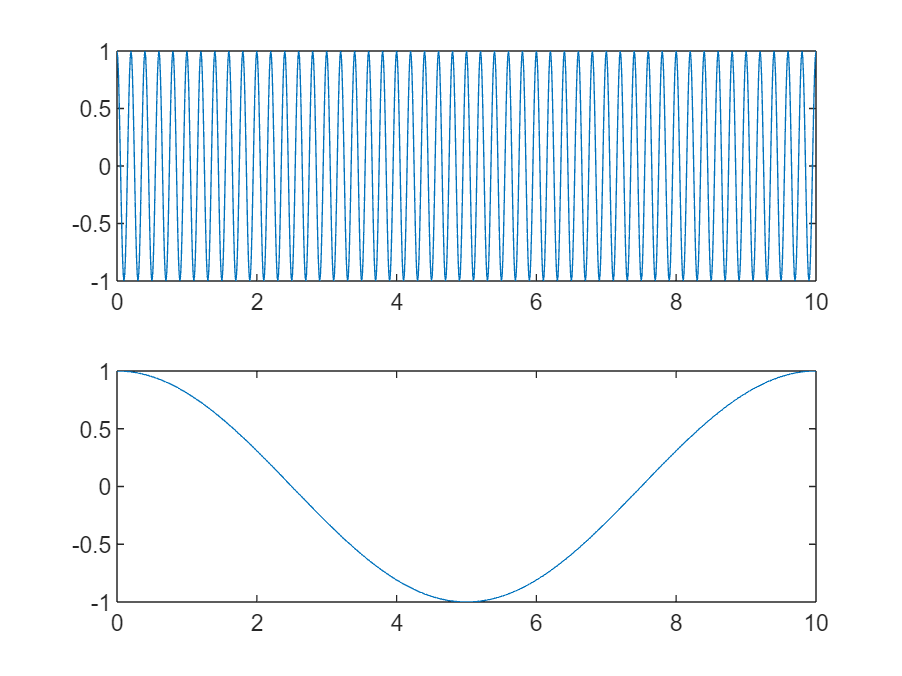

clc,clear,close all;
t=0:0.01:10;
f1=5;
f2=0.1;

figure;
subplot(2,1,1),plot(t,cos(2*pi*f1*t));
subplot(2,1,2),plot(t,cos(2*pi*f2*t));

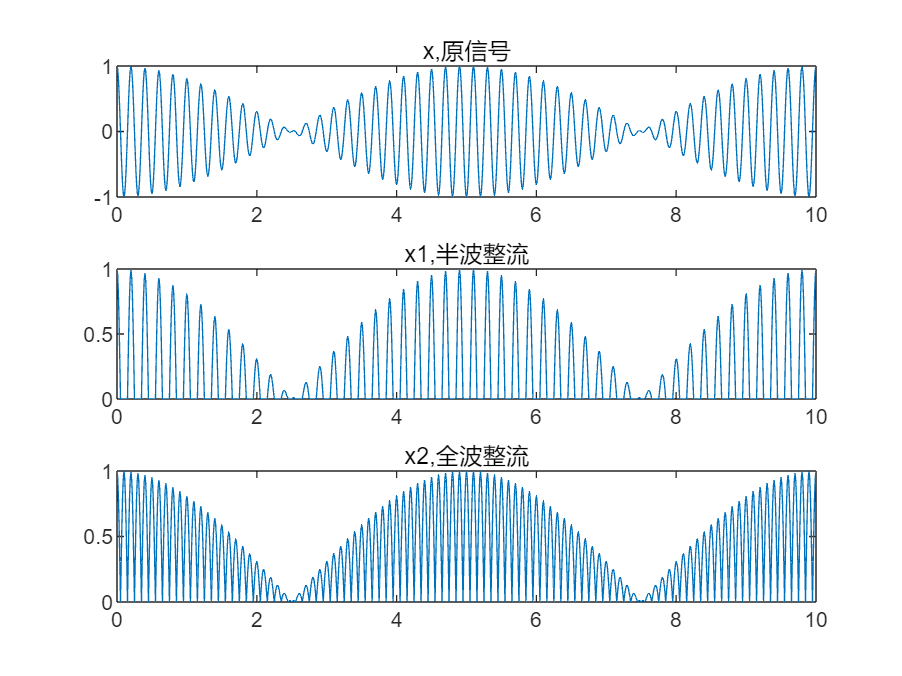

x=cos(2*pi*f1*t).*cos(2*pi*0.1*t);

x1=x;
for n=1:length(t)
    if(x(n)<0)
        x1(n)=0;
    else
        x1(n)=x(n);
    end
end
x2=abs(x);

figure;
subplot(3,1,1),plot(t,x),title('x,原信号');
subplot(3,1,2),plot(t,x1),title('x1,半波整流');
subplot(3,1,3),plot(t,x2),title('x2,全波整流');

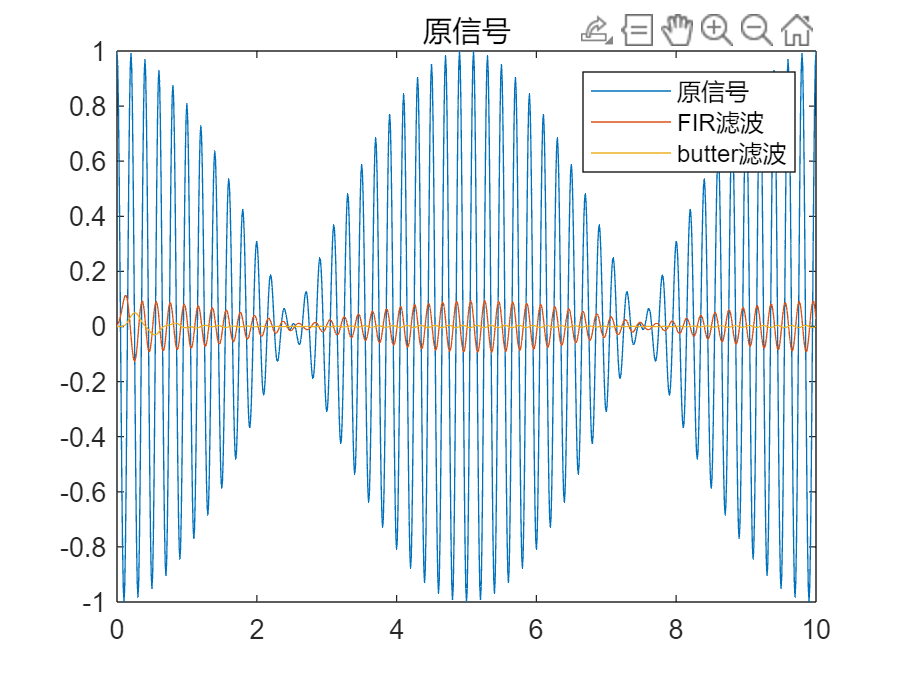


fs=100;
b2=fir1(32,1/(fs/2));
a2=1;
[b1,a1]=butter(6,2/(fs/2));

y_envelope1=filter(b2,a2,x);
y_envelope2=filter(b2,a2,x1);
y_envelope3=filter(b2,a2,x2);

y_envelope4=filter(b1,a1,x);
y_envelope5=filter(b1,a1,x1);
y_envelope6=filter(b1,a1,x2);

figure;
plot(t,x,t,y_envelope1,t,y_envelope4),legend('原信号','FIR滤波','butter滤波'),title('原信号');

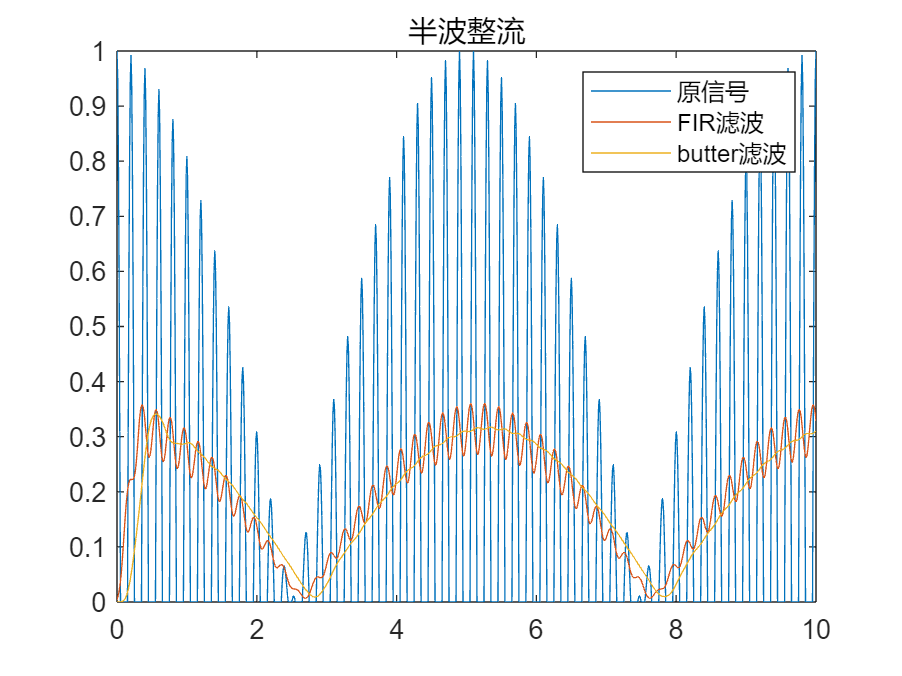

figure;
plot(t,x1,t,y_envelope2,t,y_envelope5),legend('原信号','FIR滤波','butter滤波'),title('半波整流');

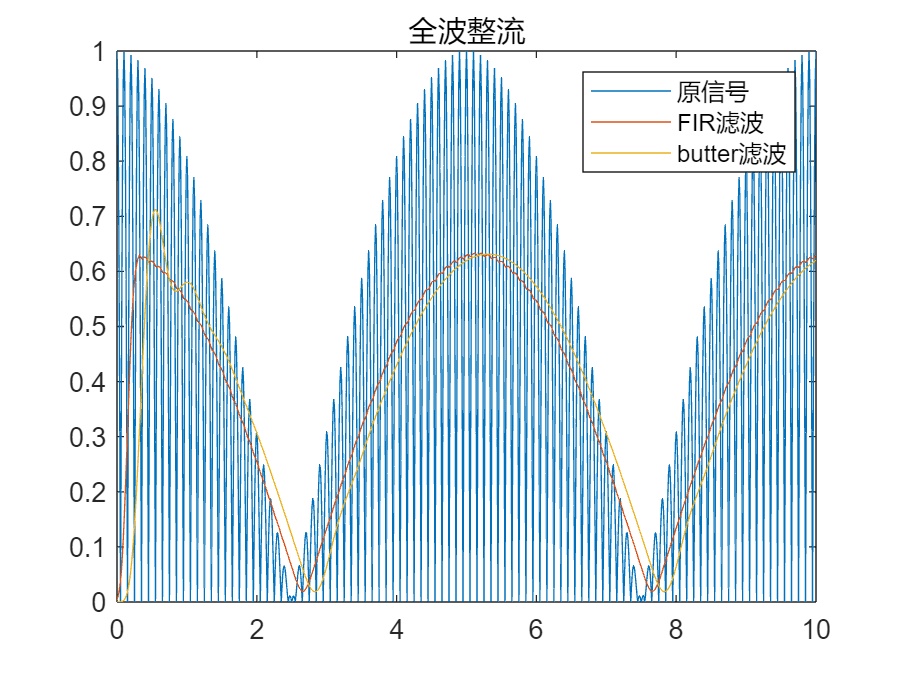

figure;
plot(t,x2,t,y_envelope3,t,y_envelope6),legend('原信号','FIR滤波','butter滤波'),title('全波整流');

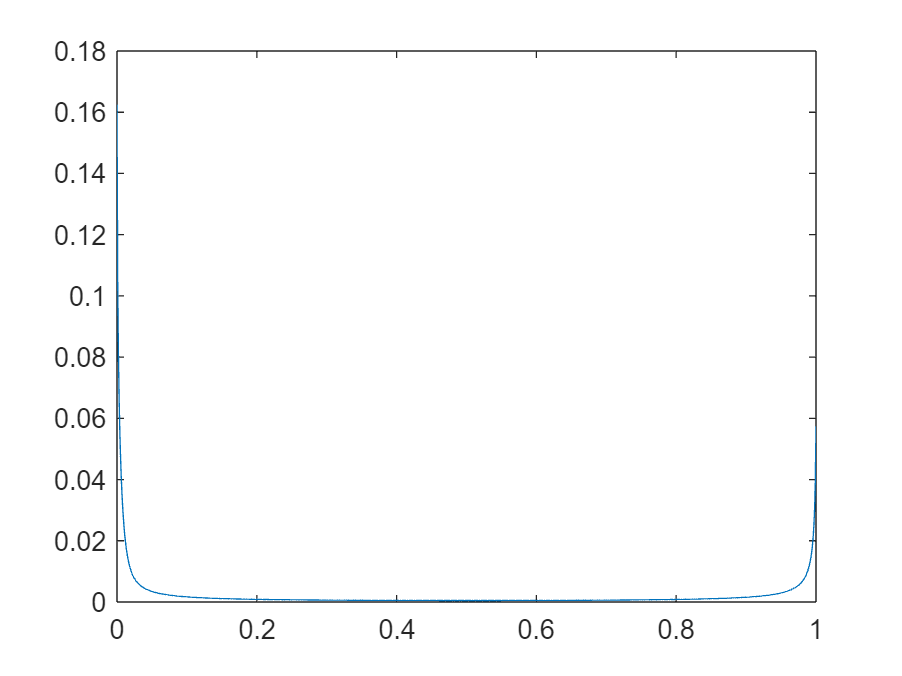

clc,clear,close all;
w=linspace(0,20*pi,1001);
t=0:0.001:1;
h2=ifft(3./(3+1j*w));
h3=3*exp(-3.*t);
figure;
plot(t,abs(h2));

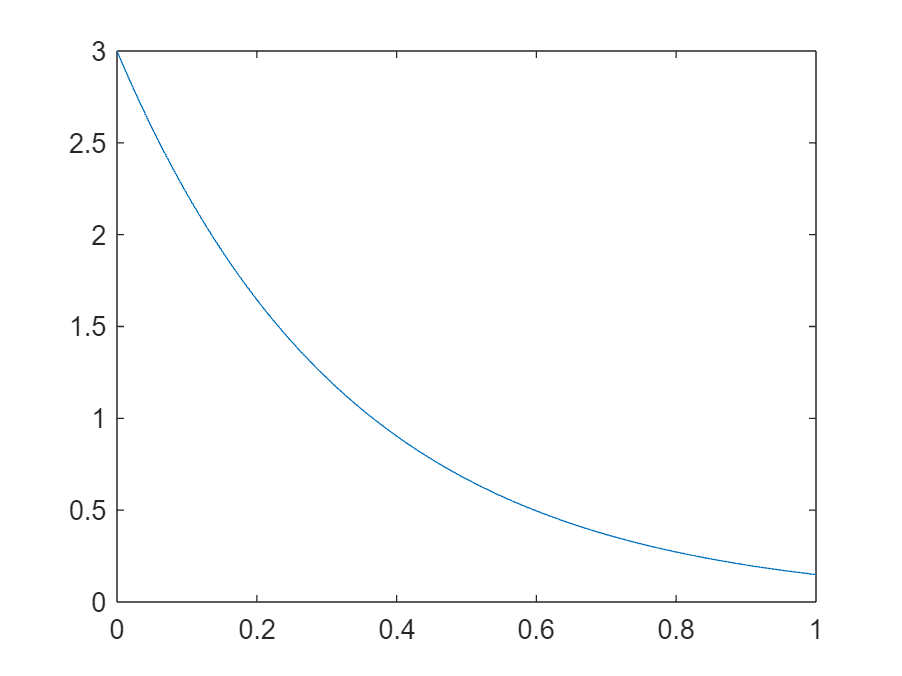

figure;
plot(t,h3);